fprintf("PLEASE SELECT AN IMAGE\n")

PLEASE SELECT AN IMAGE


i=uigetfile('*.*');
j=imread(i)

j = 865×1311×3 uint8 array
j(:,:,1) =

   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253 

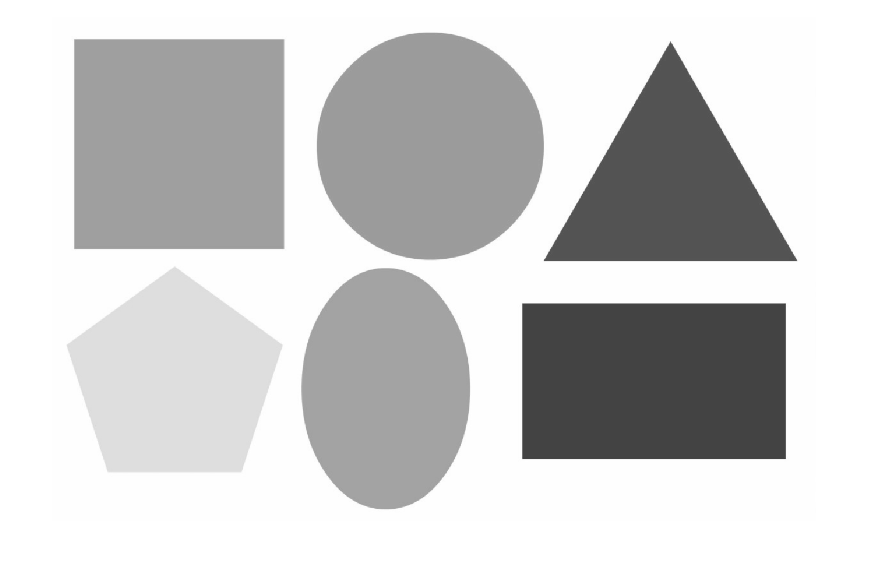

k=rgb2gray(j);
imshow(k)

[r,c]=size(k)

r = 865

c = 1311

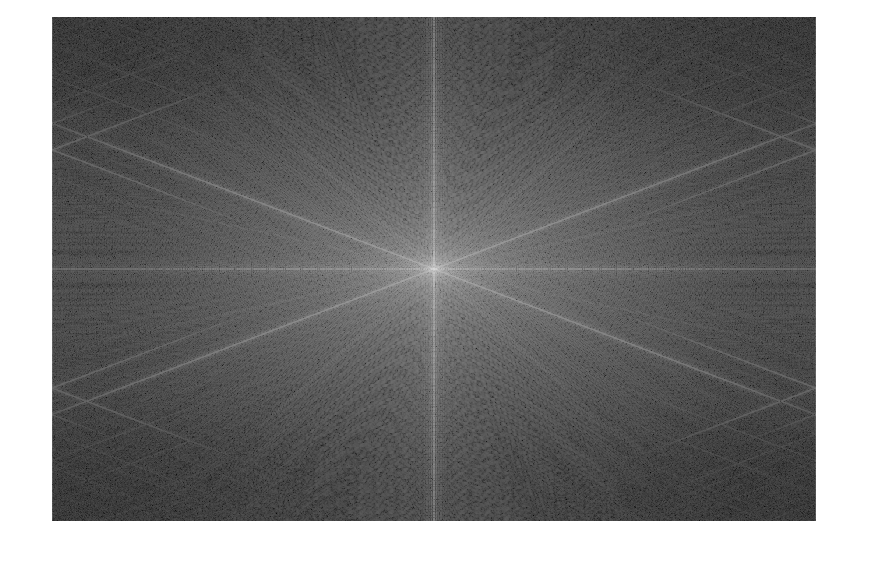

l=fft2(k);
m=fftshift(l);
n=abs(m);
o=log(1+n);
imshow(o,[]);

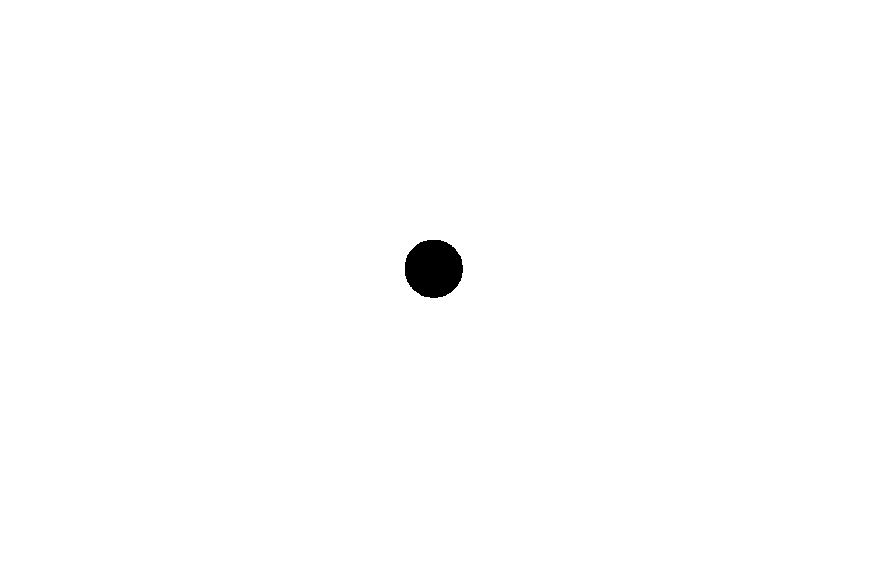

R=50;
x_c=0;
y_c=0;
[y,x]=ndgrid((-r/2)+1:r/2,(-c/2)+1:c/2);
Z= (x-x_c).^2+(y-y_c).^2 >= R^2;
imshow(Z)

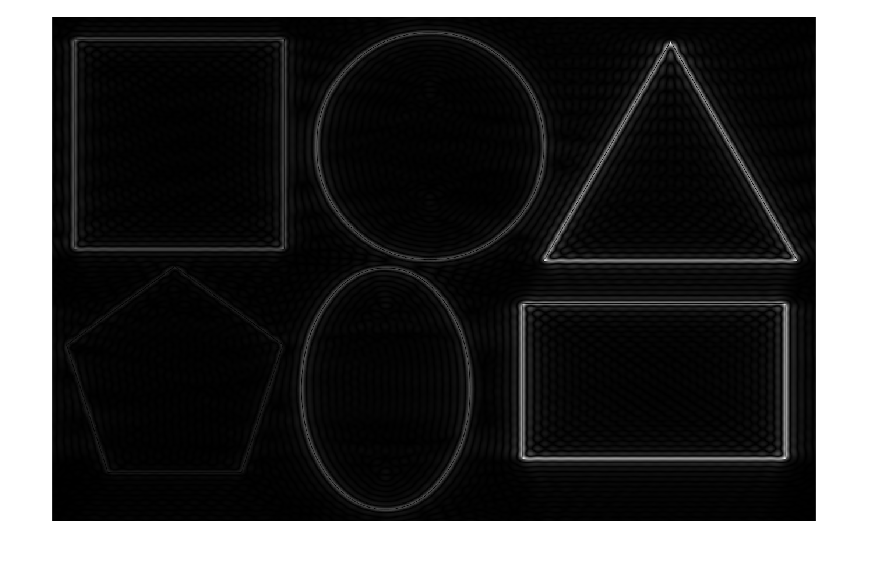

new=m.*Z;
new1=fftshift(new);
new2=ifft2(new1);
imshow(abs(new2),[]);

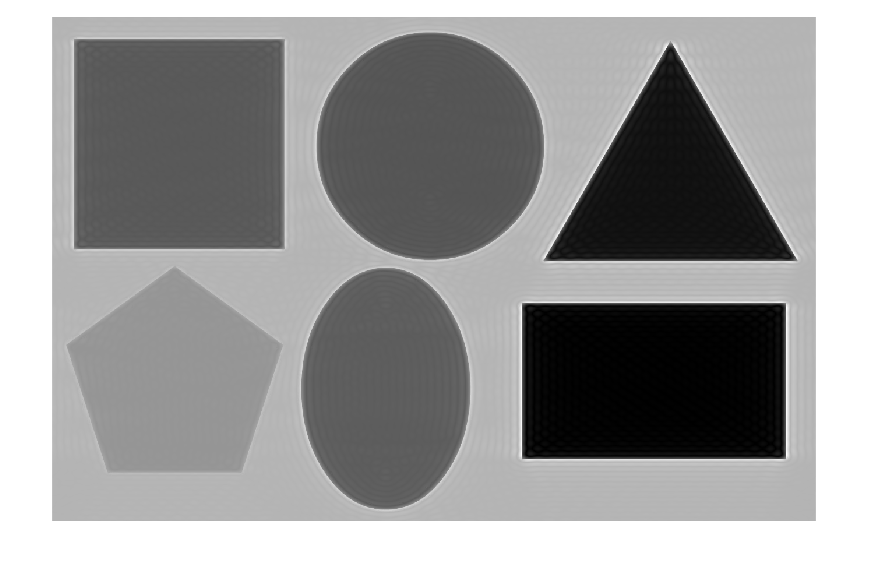

edge=abs(new2);
sharp=double(k)+edge;
imshow(sharp,[]);